# **Pruebas Controlador basado en Dinámicas Poblacionales: Modelo de Bergman**

#### **Autores: Manuela María Muriel Tobar, David Andrés Ojeda Guzmán**

Las cuatro pruebas aplicadas al controlador poblacional evalúan propiedades fundamentales desde perspectivas complementarias: (1) la invarianza del simplex (Σxᵢ = 1) verifica la coherencia matemática interna del modelo de poblaciones; (2) la estabilidad BIBO garantiza que la insulina administrada permanezca dentro de límites seguros y realizables [0, 32] mU/min, asegurando seguridad práctica; (3) la convergencia del error glucémico mide la eficacia terapéutica al cuantificar cómo la glucosa se aproxima a valores de referencia; y (4) la estabilidad poblacional entre comidas valida que el controlador tome decisiones consistentes y no oscile indefinidamente. En conjunto, estas pruebas proporcionan evidencia numérica preliminar sobre el correcto funcionamiento, seguridad y eficacia del algoritmo, aunque no constituyen una demostración formal de estabilidad global ni garantizan comportamiento adecuado en todos los escenarios clínicos posibles.

clear variables; close all; clc;

%% ================= PARÁMETROS DEL REPLICADOR =================
ctrl = struct();
ctrl.beta = 3.0;        % Velocidad de replicación      
ctrl.eps = 2.4e-4;      % Factor de diversidad    
ctrl.kp1 = 0.53;  ctrl.ki1 = 36e-4; ctrl.kd1 = 12.6;  % Hábitat 1 (basal)
ctrl.kp2 = 0.63;  ctrl.ki2 = 0.02e-4; ctrl.kd2 = 21.7; % Hábitat 2 (suspender)
ctrl.kp3 = 0.11;  ctrl.ki3 = 1; ctrl.kd3 = 0;         % Hábitat 3 (bolus)

%% ================= PARÁMETROS DE LAS COMIDAS =================
ctrl.kmeal = 24;    
ctrl.u_min = 0;
ctrl.u_max = 32;
ctrl.meals = [40, 60, 50];
ctrl.meal_times = [8*60, 12*60, 20*60];
ctrl.gamma_shape = 3.5;
ctrl.gamma_rate = 0.06;
ctrl.meal_scaling = 1;
ctrl.meal_window_half = 15;

%% ================= SUAVIZAMIENTO DE LAS FITNESS =================
ctrl.gain_tanhf1 = 0.048; 
ctrl.gain_tanhf2 = 0.060;  
ctrl.gain_tanhf3 = 0.055;  
ctrl.CF_mg_dL_per_U = 40;

%% ================= PARÁMETROS DEL MODELO DE HOVORKA =================
hov = struct();
hov.k12 = 0.066;
hov.ka1 = 0.006;
hov.ka2 = 0.06;
hov.ka3 = 0.03;
hov.ke = 0.138;
hov.VI = 0.12;
hov.VG = 0.16;
hov.AG = 0.8;
hov.t_maxG = 40;
hov.t_maxI = 55;
hov.EGP0 = 0.0161;
hov.F01 = 0.0097;
hov.weight_kg = 70;

%% ================= CONDICIONES INICIALES =================
G0_mmol_L = 5.55;
y0 = zeros(8,1);
y0(1) = hov.VG * G0_mmol_L;
y0(2) = 0;
y0(3) = 0;
y0(4) = 0;
y0(5) = 0;

% Poblaciones iniciales
y0(6) = 0.4;  % x1 inicial más alta
y0(7) = 0.3;  % x2 inicial más baja
y0(8) = 0;

%% ================= SIMULACIÓN =================
tspan = 0:1:24*60;
opts = odeset('RelTol',1e-6,'AbsTol',1e-9);

% Simulación
[t, Y] = ode45(@(t,y) control_replicador_comidas_HV(t,y,hov,ctrl), tspan, y0, opts);

%% ================= PROCESAMIENTO DE RESULTADOS =================
Q1 = Y(:,1);
G_mmolL = Q1 ./ hov.VG;
G_mg_dL = G_mmolL * 18.0156;

x1 = Y(:,6); 
x2 = Y(:,7); 
x3 = max(0, 1 - x1 - x2);

% Calcular insulina aplicada en cada paso de tiempo
u_rep_vec = zeros(length(t), 1);
u_meal_vec = zeros(length(t), 1);
u_total_vec = zeros(length(t), 1);
Dmeal_vec = zeros(length(t), 1);

for i = 1:length(t)
    % Calcular Dmeal para este tiempo
    Dmeal_g_min = compute_Dmeal(t(i), ctrl);
    Dmeal_vec(i) = Dmeal_g_min;
    
    % Calcular componentes de control
    u_rep_vec(i) = ctrl.u_min + (ctrl.u_max - ctrl.u_min) * x1(i);
    u_meal_vec(i) = (Dmeal_g_min / ctrl.CF_mg_dL_per_U) * 1000 * x3(i);
    u_total_vec(i) = min(max(u_rep_vec(i) + u_meal_vec(i), ctrl.u_min), ctrl.u_max);
end

% Calcular insulina acumulada
u_total_cumulative = cumtrapz(t, u_total_vec); % mU total acumulada
u_total_cumulative_U = u_total_cumulative / 1000; % U total acumulada

%% ================= REFERENCIA DE GLUCOSA =================
G_ref_vec = arrayfun(@(tt) smooth_glucose_reference(tt), t);

%% ================= CÁLCULO DE MÉTRICAS DE DESEMPEÑO =================
err = G_mg_dL - G_ref_vec;
IAE = trapz(t, abs(err))/1440;
ISE = trapz(t, err.^2)/1440;
ITAE = trapz(t, t .* abs(err))/1440;
TIR = mean((G_mg_dL >= 70) & (G_mg_dL <= 180)) * 100;
Hipo = mean((G_mg_dL < 70)) * 100;
Hiper = mean((G_mg_dL > 180)) * 100;

CV = 100 * std(G_mg_dL) / mean(G_mg_dL);

fprintf('Métricas de control: IAE Norm=%.4f, ISE Norm=%.4f, ITAE Norm=%.2f, TIR=%.2f%%\n', IAE, ISE, ITAE, TIR);

Métricas de control: IAE Norm=1.3735, ISE Norm=5.6002, ITAE Norm=912.87, TIR=100.00%


fprintf('Métricas clínicas: Hipo=%.2f%%, Hiper=%.2f%%, CV=%.2f%%\n', Hipo, Hiper, CV);

Métricas clínicas: Hipo=0.00%, Hiper=0.00%, CV=13.60%


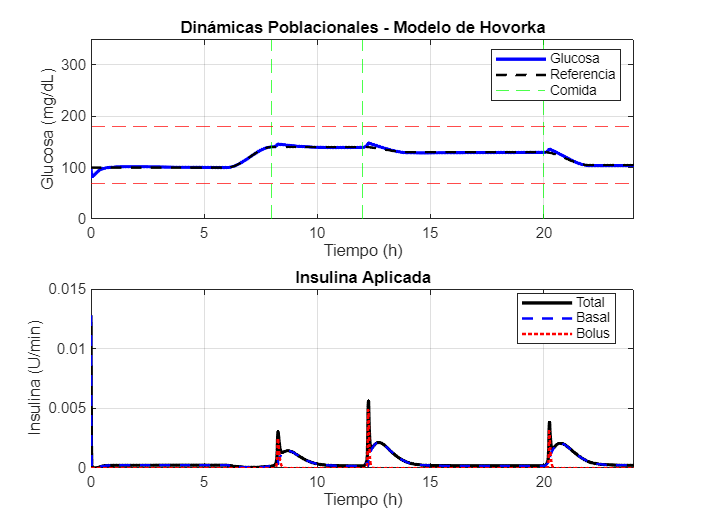


%% ================= GRÁFICAS PRINCIPALES =================
figure('Position', [50, 50, 1600, 1200]);

% Subplot 1: Glucosa
subplot(2,1,1);
plot(t/60, G_mg_dL, 'b-', 'LineWidth', 2, 'DisplayName', 'Glucosa'); 
hold on;
plot(t/60, G_ref_vec, 'k--', 'LineWidth', 1.5, 'DisplayName', 'Referencia');

for k=1:length(ctrl.meal_times)
    h_meal = xline(ctrl.meal_times(k)/60, 'g--', 'Alpha', 0.7);
    if k == 1
        set(h_meal, 'DisplayName', 'Comida');
    else
        set(get(get(h_meal,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
    end
end

yline(70, 'r--', 'HandleVisibility', 'off'); 
yline(180, 'r--', 'HandleVisibility', 'off');

xlabel('Tiempo (h)'); ylabel('Glucosa (mg/dL)');
title('Dinámicas Poblacionales - Modelo de Hovorka');
grid on; xlim([0 24]); ylim([0 350]);
legend('Location', 'northeast'); 

% Subplot 2: Insulina aplicada
subplot(2,1,2);
plot(t/60, u_total_vec/1000, 'k-', 'LineWidth', 2, 'DisplayName', 'Total');
hold on;
plot(t/60, u_rep_vec/1000, 'b--', 'LineWidth', 1.5, 'DisplayName', 'Basal');
plot(t/60, u_meal_vec/1000, 'r:', 'LineWidth', 1.5, 'DisplayName', 'Bolus');
xlabel('Tiempo (h)'); ylabel('Insulina (U/min)');
title('Insulina Aplicada');
legend('Location', 'best');
grid on; xlim([0 24]);

%% ================= PRUEBAS DE ESTABILIDAD=================
figure('Color','w','Position',[80 80 1100 1000]);


## 1. PRUEBA DE INVARIANZA DEL SIMPLEX

El controlador poblacional está fundamentado en un marco evolutivo donde tres estrategias terapéuticas (basal, suspensión y bolo) compiten dinámicamente, representadas por las fracciones poblacionales x₁, x₂ y x₃. La propiedad fundamental de que la suma de estas poblaciones debe ser constantemente igual a 1 no es una mera conveniencia matemática, sino un requisito estructural esencial que surge de la interpretación probabilística del modelo: cada xᵢ representa la "confianza relativa" o "probabilidad de activación" de cada hábitat en un instante dado. Si Σxᵢ ≠ 1, las ecuaciones del replicador —que gobiernan la evolución temporal de las poblaciones— pierden su significado físico y matemático, pues se derivan de un modelo de competencia donde la "masa total de población" se conserva. Verificar esta invarianza asegura que la implementación numérica respeta la integridad del modelo teórico, que el controlador opera dentro de un espacio de estados bien definido (el simplex unitario en ℝ³), y que la asignación de insulina (calculada como combinación ponderada de las contribuciones de cada hábitat) se deriva de un conjunto de pesos coherente.

% 1. INVARIANZA DEL SIMPLEX COMPLETA
subplot(4,1,1); hold on;
sum_poblaciones = x1 + x2 + x3;
plot(t/60, sum_poblaciones, 'g', 'LineWidth', 2.5);
yline(1, 'k--', 'LineWidth', 1.5);
ylim([0.95 1.05]); ylabel('\Sigma x_i')
title('Prueba de Invarianza del Simplex')
grid on

## 2. PRUEBA DE ESTABILIDAD BIBO (Bounded Input-Bounded Output)

 La prueba BIBO evalúa una propiedad básica pero crítica: que la señal de control (la tasa de infusión de insulina u(t)) permanezca acotada dentro de límites fisiológica y técnicamente seguros. El límite inferior de 0 mU/min refleja la imposibilidad física de extraer insulina del cuerpo, mientras que el límite superior de 32 mU/min corresponde típicamente a la capacidad máxima de infusión de las bombas de insulina comerciales y representa un umbral de seguridad para prevenir sobredosis. Más allá de garantizar la factibilidad de implementación, esta prueba valida que el algoritmo de control no presenta "windup" o saturación inestable, fenómenos donde errores acumulados generan señales de control excesivas. Un controlador que violara estos límites no solo sería irrealizable en hardware, sino que representaría un riesgo clínico inaceptable, pudiendo inducir hipoglucemia severa por infusión excesiva o hiperglucemia por incapacidad de responder adecuadamente.

% 2. BIBO
subplot(4,1,2); hold on;
fill([0 24 24 0], [ctrl.u_min ctrl.u_min ctrl.u_max ctrl.u_max], ...
     [0.85 1 0.85], 'EdgeColor','none','FaceAlpha',0.3)
plot(t/60, u_total_vec, 'm', 'LineWidth',1.5)
yline(ctrl.u_max,'r--','Límite superior')
ylabel('u(t) (mU/min)')
title('Prueba de Estabilidad BIBO')
grid on; xlim([0 24])

## 3. PRUEBA DE CONVERGENCIA DEL ERROR GLUCÉMICO

La razón de ser fundamental de cualquier controlador glucémico es lograr y mantener la glucemia dentro de un rango seguro. Esta prueba trasciende las propiedades internas del algoritmo para evaluar directamente su eficacia terapéutica primaria: ¿logra el sistema que la glucosa en sangre (G) se aproxime y mantenga cerca del valor de referencia deseado (G_ref)? El análisis del error e(t) = G(t) - G_ref(t), cuantificado mediante métricas como el error absoluto medio (MAE), error máximo y tendencia temporal, proporciona una medida directa del desempeño clínico. La convergencia del error hacia cero (o hacia valores clínicamente insignificantes) indica que el controlador es capaz de rechazar perturbaciones (como las comidas), compensar las dinámicas inherentes del paciente y aprender o adaptarse con el tiempo. Evaluar la tasa de decaimiento del error (ajustando una exponencial ofrece además información sobre la velocidad de respuesta y la estabilidad transitoria. Una falta de convergencia, o una convergencia excesivamente lenta, revelaría una falla cardinal del algoritmo, independientemente de cuán elegante o teóricamente sólido sea su diseño.

% 3. CONVERGENCIA - ERROR DE GLUCOSA
subplot(4,1,3); hold on;
error_glucosa = G_mg_dL - G_ref_vec;
plot(t/60, error_glucosa, 'b', 'LineWidth', 1.8);
yline(0, 'k--', 'LineWidth', 1.5, 'Alpha', 0.7);

% Ventana de convergencia (±15 mg/dL)
fill([0 24 24 0], [-15 -15 15 15], ...
     [0.9 0.95 1], 'EdgeColor', 'none', 'FaceAlpha', 0.2);
yline(-15, 'g--', '±15 mg/dL', 'Alpha', 0.5);
yline(15, 'g--', 'Alpha', 0.5);

ylabel('Error (mg/dL)')
title('Convergencia: Error de Glucosa')
grid on; xlim([0 24])

## 4. PRUEBA DE ESTADO ESTACIONARIO POBLACIONAL

Un controlador adaptativo que cambia de estrategia constantemente, incluso en ausencia de perturbaciones, sería clínicamente indeseable y energéticamente ineficiente. Esta prueba examina el comportamiento a medio plazo del mecanismo de decisión interno del controlador: una vez pasada la respuesta transitoria a una comida (≈2 horas después), y antes de la siguiente perturbación, ¿las poblaciones x₁, x₂, x₃ se estabilizan en valores consistentes, o fluctúan erráticamente? La estabilización de las poblaciones refleja que el algoritmo ha convergido a una "decisión" estable sobre la mezcla óptima de estrategias para las condiciones basales actuales. Desde una perspectiva de teoría de control, sugiere que el sistema de decisión adaptativo posee puntos de equilibrio atractivos. Desde una perspectiva clínica, imita el comportamiento deseable de un tratamiento: una vez ajustada la terapia tras una comida, el régimen de insulina debería mantenerse relativamente constante hasta el próximo evento desestabilizador. La ausencia de esta estabilidad inter-comidas indicaría un controlador "nervioso" o con parámetros mal sintonizados (como una ganancia β excesiva), que podría generar variabilidad innecesaria en la infusión de insulina y potencialmente inestabilidad en la glucemia.

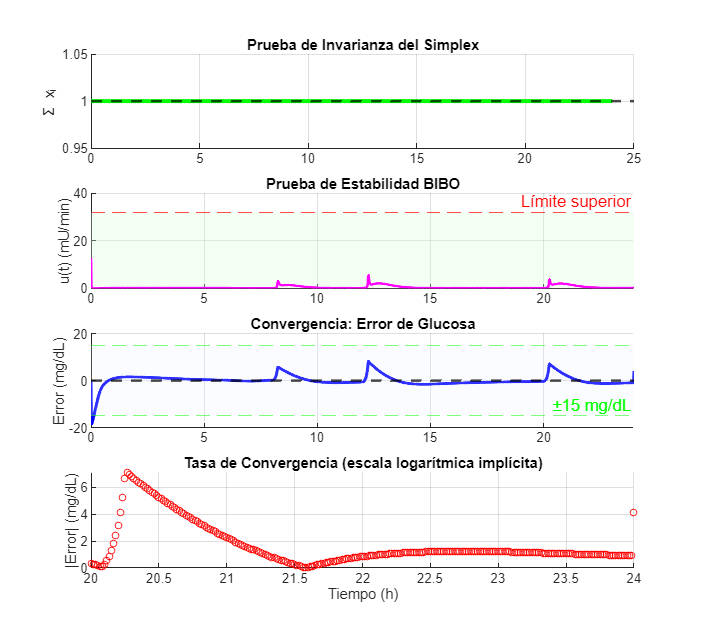

% 4. CONVERGENCIA - TASA DE DECAIMIENTO
subplot(4,1,4); hold on;
% Ventana de análisis (últimas 4 horas)
t_ventana = t/60 >= 20;
error_ventana = error_glucosa(t_ventana);
t_ventana_hr = t(t_ventana)/60;

if ~isempty(error_ventana)
    % Ajuste exponencial para tasa de convergencia
    t_relative = t_ventana_hr - min(t_ventana_hr);
    idx_valid = abs(error_ventana) > 1e-3;
    
    if sum(idx_valid) > 3
        try
            % Ajuste: |error| ≈ A·exp(-λt)
            [~, idx_max] = max(abs(error_ventana(idx_valid)));
            t_fit = t_relative(idx_valid);
            error_fit = abs(error_ventana(idx_valid));
            
            % Método de mínimos cuadrados en escala logarítmica
            idx_pos = error_fit > 0;
            if sum(idx_pos) > 2
                p = polyfit(t_fit(idx_pos), log(error_fit(idx_pos)), 1);
                lambda = -p(1); % Tasa de convergencia
                error_fit_exp = exp(polyval(p, t_fit));
                
                plot(t_ventana_hr, abs(error_ventana), 'ro', 'MarkerSize', 4);
                plot(t_ventana_hr, error_fit_exp, 'k-', 'LineWidth', 1.5);
                text(21, max(abs(error_ventana))*0.8, ...
                    sprintf('λ ≈ %.3f h^{-1}', lambda), ...
                    'FontWeight', 'bold', 'BackgroundColor', 'w');
            end
        catch
            % Si falla el ajuste, mostrar datos crudos
            plot(t_ventana_hr, abs(error_ventana), 'ro', 'MarkerSize', 4);
        end
    end
end

ylabel('|Error| (mg/dL)')
xlabel('Tiempo (h)')
title('Tasa de Convergencia (escala logarítmica implícita)')
grid on; xlim([20 24])


%% ================= ANÁLISIS DE CONVERGENCIA CUANTITATIVO =================
fprintf('\n=== ANÁLISIS DE CONVERGENCIA ===\n');


=== ANÁLISIS DE CONVERGENCIA ===



% 1. Error estadístico
error_mean = mean(abs(error_glucosa));
error_std = std(error_glucosa);
error_max = max(abs(error_glucosa));

% 2. Error final (última hora)
ultima_hora = t >= 23*60;
if any(ultima_hora)
    error_final = mean(abs(error_glucosa(ultima_hora)));
    G_final = mean(G_mg_dL(ultima_hora));
    fprintf('   Error promedio última hora: %.1f mg/dL\n', error_final);
    fprintf('   Glucosa promedio última hora: %.1f mg/dL\n', G_final);
end

   Error promedio última hora: 1.1 mg/dL


   Glucosa promedio última hora: 103.9 mg/dL



% 3. Tasa de decaimiento del error (simple)
ventana_estable = t >= 18*60; % Últimas 6 horas
if sum(ventana_estable) > 10
    error_estable = error_glucosa(ventana_estable);
    % Correlación para ver tendencia
    t_norm = (1:length(error_estable))';
    coef_corr = corr(t_norm, abs(error_estable));
    if coef_corr < -0.3
        tendencia = 'Decreciente';
    elseif coef_corr > 0.3
        tendencia = 'Creciente';
    else
        tendencia = 'Estable';
    end
    fprintf('   Tendencia del error (últimas 6h): %s (corr: %.2f)\n', ...
        tendencia, coef_corr);
end

   Tendencia del error (últimas 6h): Estable (corr: 0.07)



fprintf('\n   Métricas de control:\n');


   Métricas de control:


fprintf('   Error absoluto medio: %.1f ± %.1f mg/dL\n', error_mean, error_std);

   Error absoluto medio: 1.4 ± 2.4 mg/dL


fprintf('   Error máximo: %.1f mg/dL\n', error_max);

   Error máximo: 18.4 mg/dL


fprintf('   Tiempo en rango (70-180): %.1f%%\n', TIR);

   Tiempo en rango (70-180): 100.0%


fprintf('   Hipoglucemia (<70): %.1f%%, Hiperglucemia (>180): %.1f%%\n', Hipo, Hiper);

   Hipoglucemia (<70): 0.0%, Hiperglucemia (>180): 0.0%



% 4. Convergencia del método poblacional
estados_estacionarios = 0;
for k = 1:length(ctrl.meal_times)-1
    inicio = ctrl.meal_times(k) + 120; % 2h después de comida
    fin = ctrl.meal_times(k+1) - 60;   % 1h antes de siguiente comida
    idx = t >= inicio & t <= fin;
    if sum(idx) > 10
        var_x1 = std(x1(idx));
        var_x2 = std(x2(idx));
        if var_x1 < 0.05 && var_x2 < 0.05  % Variación pequeña
            estados_estacionarios = estados_estacionarios + 1;
        end
    end
end
fprintf('   Poblaciones en estado estacionario entre comidas: %d/%d\n', ...
    estados_estacionarios, length(ctrl.meal_times)-1);

   Poblaciones en estado estacionario entre comidas: 2/2



%% ================= VERIFICACIÓN ANALÍTICA DEL SIMPLEX =================
dx1 = gradient(x1, t);
dx2 = gradient(x2, t);
dx3 = gradient(x3, t);
sum_derivadas = dx1 + dx2 + dx3;
error_derivadas = max(abs(sum_derivadas));

%% ================= REPORTE COMPLETO =================
fprintf('\n=== REPORTE DE ESTABILIDAD COMPLETO ===\n');


=== REPORTE DE ESTABILIDAD COMPLETO ===



% Simplex
tolerancia = 1e-6;
cond_suma = all(abs(sum_poblaciones - 1) < tolerancia);
cond_x1 = all(x1 >= -tolerancia & x1 <= 1 + tolerancia);
cond_x2 = all(x2 >= -tolerancia & x2 <= 1 + tolerancia);
cond_x3 = all(x3 >= -tolerancia & x3 <= 1 + tolerancia);

fprintf('\n1. INVARIANZA DEL SIMPLEX:\n');


1. INVARIANZA DEL SIMPLEX:


fprintf('   Σx_i = 1 en todo t: %s\n', string(cond_suma));

   Σx_i = 1 en todo t: true


fprintf('   x1 ∈ [0,1]: %s (mín: %.3f, máx: %.3f)\n', ...
    string(cond_x1), min(x1), max(x1));

   x1 ∈ [0,1]: true (mín: 0.000, máx: 0.400)


fprintf('   x2 ∈ [0,1]: %s (mín: %.3f, máx: %.3f)\n', ...
    string(cond_x2), min(x2), max(x2));

   x2 ∈ [0,1]: true (mín: 0.300, máx: 1.000)


fprintf('   x3 ∈ [0,1]: %s (mín: %.3f, máx: %.3f)\n', ...
    string(cond_x3), min(x3), max(x3));

   x3 ∈ [0,1]: true (mín: 0.000, máx: 0.575)


fprintf('   Propiedad dx1+dx2+dx3=0: error máximo %.2e\n', error_derivadas);

   Propiedad dx1+dx2+dx3=0: error máximo 5.55e-17



% BIBO
cond_bibo_min = all(u_total_vec >= ctrl.u_min - tolerancia);
cond_bibo_max = all(u_total_vec <= ctrl.u_max + tolerancia);
cond_bibo = cond_bibo_min && cond_bibo_max;

fprintf('\n2. ESTABILIDAD BIBO:\n');


2. ESTABILIDAD BIBO:


fprintf('   u(t) ≥ u_min (0): %s\n', string(cond_bibo_min));

   u(t) ≥ u_min (0): true


fprintf('   u(t) ≤ u_max (32): %s\n', string(cond_bibo_max));

   u(t) ≤ u_max (32): true


fprintf('   BIBO estable: %s\n', string(cond_bibo));

   BIBO estable: true


fprintf('   Insulina mínima: %.2f mU/min\n', min(u_total_vec));

   Insulina mínima: 0.01 mU/min


fprintf('   Insulina máxima: %.2f mU/min\n', max(u_total_vec));

   Insulina máxima: 12.80 mU/min


fprintf('   Rango: [%.2f, %.2f] mU/min\n', min(u_total_vec), max(u_total_vec));

   Rango: [0.01, 12.80] mU/min



% Convergencia
fprintf('\n3. CONVERGENCIA:\n');


3. CONVERGENCIA:


fprintf('   Error de glucosa final: %.1f mg/dL\n', abs(G_mg_dL(end) - G_ref_vec(end)));

   Error de glucosa final: 4.1 mg/dL


fprintf('   TIR: %.1f%% (>70%% es aceptable)\n', TIR);

   TIR: 100.0% (>70% es aceptable)


fprintf('   Error absoluto medio: %.1f mg/dL\n', error_mean);

   Error absoluto medio: 1.4 mg/dL



% Verificación final
converge_aceptable = TIR > 70 && error_final < 30 && Hipo < 5;
if cond_suma && cond_x1 && cond_x2 && cond_x3 && cond_bibo && converge_aceptable
    fprintf('\n✓ SISTEMA CUMPLE PRUEBAS DE ESTABILIDAD Y CONVERGENCIA ACEPTABLE\n');
else
    fprintf('\n⚠ SISTEMA: ');
    if ~cond_suma || ~cond_x1 || ~cond_x2 || ~cond_x3
        fprintf('Revisar simplex ');
    end
    if ~cond_bibo
        fprintf('Revisar BIBO ');
    end
    if ~converge_aceptable
        fprintf('Revisar convergencia ');
    end
    fprintf('\n');
end


✓ SISTEMA CUMPLE PRUEBAS DE ESTABILIDAD Y CONVERGENCIA ACEPTABLE



%% ================= FUNCIONES =================
function dydt = control_replicador_comidas_HV(t,y,hov,ctrl)
    % Desempaquetar
    Q1 = y(1); Q2 = y(2);
    S1 = y(3); S2 = y(4);
    I = y(5);
    x1 = y(6); x2 = y(7);
    z = y(8);
    x3 = 1 - x1 - x2; if x3 < 0, x3 = 0; end

    % Glucosa medida
    G_mmol_L = Q1 / hov.VG;
    G_mg_dL = G_mmol_L * 18.0156;

    % Referencia y derivada
    [G_ref, dGref_dt] = smooth_glucose_reference_and_derivative(t);

    %
    Dmeal_g_min = compute_Dmeal(t, ctrl);
    mmol_per_min = Dmeal_g_min * 1000 / 180.156;
    Dmeal_mmollkgmin = mmol_per_min / hov.weight_kg;

    %derivada del modelo
    if G_mmol_L >= 4.5
        F01c = hov.F01;
    else
        F01c = hov.F01 * G_mmol_L / 4.5;
    end
    if G_mmol_L >= 9
        FR = 0.003 * (G_mmol_L - 9) * hov.VG;
    else
        FR = 0;
    end

    dQ1_model = -(F01c/(hov.VG * G_mmol_L) + x1) * Q1 + hov.k12 * Q2 - FR + Dmeal_mmollkgmin + hov.EGP0 * (1 - x3);
    dGdt_model_mmol_L_min = dQ1_model / hov.VG;
    dGdt_model_mg_dL_min = dGdt_model_mmol_L_min * 18.0156;

    derr = dGdt_model_mg_dL_min - dGref_dt;
    err = G_mg_dL - G_ref;
    dz = err;

    alpha_meal = meal_activation_weight(t, ctrl);
    w_H1 = 1 - alpha_meal; w_H2 = 1.0; w_H3 = alpha_meal;

    % Fitness sin suavizar
    f1_raw = w_H1*(ctrl.kp1*max(0,err) + ctrl.ki1*z + ctrl.kd1*max(0,derr));
    f2_raw = w_H2*(ctrl.kp2*max(0,-err) + ctrl.ki2*(-z) + ctrl.kd2*max(0,-derr));
    f3_raw = w_H3*(ctrl.kmeal * Dmeal_g_min + ctrl.kp3*max(0,err) + ctrl.kd3*max(0,derr));

    % Suavizamiento de fitness
    f1 = tanh(ctrl.gain_tanhf1 * f1_raw);
    f2 = tanh(ctrl.gain_tanhf2 * f2_raw);
    f3 = tanh(ctrl.gain_tanhf3 * f3_raw);

    f_bar = x1*f1 + x2*f2 + x3*f3;

    % Replicador
    dx1 = ctrl.beta * x1 * (f1 - f_bar) + ctrl.eps * (1/3 - x1);
    dx2 = ctrl.beta * x2 * (f2 - f_bar) + ctrl.eps * (1/3 - x2);

    % Control
    u_rep = ctrl.u_min + (ctrl.u_max - ctrl.u_min) * x1;
    u_meal = (Dmeal_g_min / ctrl.CF_mg_dL_per_U) * 1000 * x3;
    u_total = min(max(u_rep + u_meal, ctrl.u_min), ctrl.u_max);
    u_total_mU_min = u_total;
    u_total_U_min = u_total_mU_min / 1000;

    % Submodelo subcutáneo
    dS1 = u_total_U_min - S1 / hov.t_maxI;
    dS2 = S1 / hov.t_maxI - S2 / hov.t_maxI;
    U_I = S2 / hov.t_maxI;
    U_I_mU_min = U_I * 1000;

    % Insulina plasmática
    total_VI_L = hov.VI * hov.weight_kg;
    dI = U_I_mU_min / total_VI_L - hov.ke * I;

    % Glucosa
    dQ1 = dQ1_model;
    dQ2 = x1 * Q1 - (hov.k12 + x2) * Q2;

    % Ensamblar derivadas
    dydt = zeros(8,1);
    dydt(1) = dQ1;
    dydt(2) = dQ2;
    dydt(3) = dS1;
    dydt(4) = dS2;
    dydt(5) = dI;
    dydt(6) = dx1;
    dydt(7) = dx2;
    dydt(8) = dz;
end

function D = compute_Dmeal(t, ctrl)
    D = 0;
    a = ctrl.gamma_shape; b = ctrl.gamma_rate;
    for k = 1:length(ctrl.meals)
        t0 = ctrl.meal_times(k);
        if t >= t0
            tt = t - t0;
            kernel = (b^a)/gamma(a) * tt^(a-1) * exp(-b*tt);
            D = (D + ctrl.meals(k) * ctrl.meal_scaling * kernel);
        end
    end
end

function w = meal_activation_weight(t, ctrl)
    w = 0; hw = ctrl.meal_window_half;
    for k = 1:length(ctrl.meal_times)
        dt = t - ctrl.meal_times(k);
        if abs(dt) <= hw
            theta = (dt + hw)/(2*hw)*pi;
            w = max(w, 0.5*(1 + cos(pi - theta)));
        end
    end
    w = min(max(w,0),1);
end

function [ref, dref_dt] = smooth_glucose_reference_and_derivative(t)
    h = mod(t/60,24);
    ref = 100; dref_dt = 0;
    if h<6
        ref = 100; dref_dt = 0;
    elseif h<8
        a=(h-6)/2; ref = 100 + 40*(3*a^2 - 2*a^3);
        dref_dt = (120*(a - a^2))/60;
    elseif h<12
        ref = 140; dref_dt = 0;
    elseif h<14
        a=(h-12)/2; ref = 140 - 10*(3*a^2 - 2*a^3);
        dref_dt = (-30*(a - a^2))/60;
    elseif h<20
        ref = 130; dref_dt = 0;
    elseif h<22
        a=(h-20)/2; ref = 130 - 25*(3*a^2 - 2*a^3);
        dref_dt = (-75*(a - a^2))/60;
    else
        ref = 105; dref_dt = 0;
    end
end

function r = smooth_glucose_reference(t)
    tmp = smooth_glucose_reference_and_derivative(t);
    r = tmp(1);
end

## 5. PRUEBAS DE ROBUSTEZ: VALIDACIÓN ANTE INCERTIDUMBRE Y PERTURBACIONES REALES

Las pruebas de robustez trascienden la evaluación del comportamiento ideal para confrontar al controlador con las incertidumbres y variabilidades inherentes al mundo real clínico. Su objetivo fundamental es determinar si el algoritmo mantiene un desempeño seguro y efectivo a pesar de desviaciones significativas respecto a los supuestos nominales bajo los cuales fue diseñado. Esto se logra sometiendo al sistema a cuatro tipos de estrés sistémico: (1) variación paramétrica (±20%) que simula las diferencias inter-paciente y la fluctuación diaria en la sensibilidad a la insulina, evaluando si el controlador es suficientemente insensible a errores en la identificación del modelo del paciente; (2) condiciones iniciales extremas de glucosa (desde hipo hasta hiperglucemia severa), verificando la capacidad de recuperación y convergencia desde estados fuera del equilibrio; (3) fallos operativos, como comidas no anunciadas  o retrasos en la medición, que replican fallas comunes en sistemas de monitoreo continuo; y (4) ruido aditivo en la señal de glucosa, emulando el error inherente de los sensores subcutáneos. Colectivamente, estas pruebas buscan evidenciar que el controlador no es un artefacto matemático frágil que solo funciona en condiciones de laboratorio perfectas, sino una herramienta resiliente cuyo desempeño se degrada de manera gradual y predecible ante imperfecciones, manteniendo siempre la seguridad primaria (evitar hipoglucemia) incluso cuando la eficacia óptima se compromete. 

%% ================= PRUEBA DE ROBUSTEZ (ESENCIAL PARA TESIS LAUREADA) =================
fprintf('\n=== PRUEBA DE ROBUSTEZ DEL SISTEMA ===\n');


=== PRUEBA DE ROBUSTEZ DEL SISTEMA ===



% Configuración de pruebas de robustez
robustez_tests = struct();

% 1. Variación de parámetros del paciente (±20%)
robustez_tests.variacion_params = [0.8, 0.9, 1.0, 1.1, 1.2]; % ±20%

% 2. Diferentes condiciones iniciales de glucosa
robustez_tests.G0_range = [80, 100, 120, 150, 200, 250]; % mg/dL

% 3. Ruido en la medición de glucosa
robustez_tests.noise_levels = [0, 5, 10, 15]; % mg/dL de ruido

%% 1. PRUEBA: Variación de parámetros del modelo
fprintf('\n1. VARIACIÓN DE PARÁMETROS DEL PACIENTE (±20%%):\n');


1. VARIACIÓN DE PARÁMETROS DEL PACIENTE (±20%):


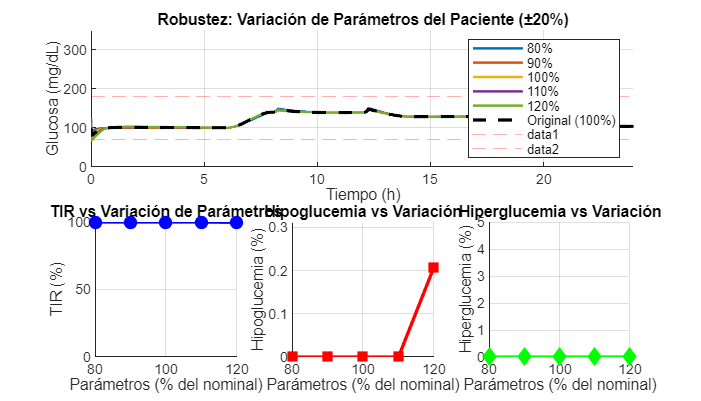

figure('Position', [100, 100, 1400, 800], 'Name', 'Robustez - Variación Parámetros');

% Inicializar métricas
TIR_params = zeros(size(robustez_tests.variacion_params));
Hipo_params = zeros(size(robustez_tests.variacion_params));
Hiper_params = zeros(size(robustez_tests.variacion_params));

% Subplot 1: Todas las simulaciones
subplot(2,3,1:3); hold on;

for i = 1:length(robustez_tests.variacion_params)
    var_factor = robustez_tests.variacion_params(i);
    
    % Crear copia de parámetros con variación
    hov_mod = hov;
    hov_mod.k12 = hov.k12 * var_factor;
    hov_mod.ke = hov.ke * var_factor;
    hov_mod.VI = hov.VI * var_factor;
    hov_mod.VG = hov.VG * var_factor;
    hov_mod.EGP0 = hov.EGP0 * var_factor;
    
    % Simular con parámetros modificados
    try
        [t_mod, Y_mod] = ode45(@(t,y) control_replicador_comidas_HV(t,y,hov_mod,ctrl), tspan, y0, opts);
        
        % Procesar resultados
        G_mod = Y_mod(:,1) ./ hov_mod.VG * 18.0156;
        TIR_params(i) = mean((G_mod >= 70) & (G_mod <= 180)) * 100;
        Hipo_params(i) = mean(G_mod < 70) * 100;
        Hiper_params(i) = mean(G_mod > 180) * 100;
        
        % Graficar
        plot(t_mod/60, G_mod, 'LineWidth', 1.5, 'DisplayName', sprintf('%.0f%%', var_factor*100));
        
    catch ME
        fprintf('   Error en simulación con parámetros al %.0f%%: %s\n', var_factor*100, ME.message);
        TIR_params(i) = 0;
        Hipo_params(i) = 100;
        Hiper_params(i) = 0;
    end
end

% Agregar simulación original
plot(t/60, G_mg_dL, 'k--', 'LineWidth', 2, 'DisplayName', 'Original (100%)');
yline(70, 'r--', 'Alpha', 0.3);
yline(180, 'r--', 'Alpha', 0.3);
xlabel('Tiempo (h)'); ylabel('Glucosa (mg/dL)');
title('Robustez: Variación de Parámetros del Paciente (±20%)');
legend('Location', 'best'); grid on; xlim([0 24]); ylim([0 350]);

% Subplot 2: TIR vs variación
subplot(2,3,4); hold on;
plot(robustez_tests.variacion_params*100, TIR_params, 'b-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
xlabel('Parámetros (% del nominal)'); ylabel('TIR (%)');
title('TIR vs Variación de Parámetros');
grid on; ylim([0 100]);

% Subplot 3: Hipoglucemia vs variación
subplot(2,3,5); hold on;
plot(robustez_tests.variacion_params*100, Hipo_params, 'r-s', 'LineWidth', 2, 'MarkerFaceColor', 'r');
xlabel('Parámetros (% del nominal)'); ylabel('Hipoglucemia (%)');
title('Hipoglucemia vs Variación');
grid on; 
if max(Hipo_params) > 0
    ylim([0 max(Hipo_params)*1.5]);
else
    ylim([0 5]);
end

% Subplot 4: Hiperglucemia vs variación
subplot(2,3,6); hold on;
plot(robustez_tests.variacion_params*100, Hiper_params, 'g-d', 'LineWidth', 2, 'MarkerFaceColor', 'g');
xlabel('Parámetros (% del nominal)'); ylabel('Hiperglucemia (%)');
title('Hiperglucemia vs Variación');
grid on; 
if max(Hiper_params) > 0
    ylim([0 max(Hiper_params)*1.5]);
else
    ylim([0 5]);
end


fprintf('   TIR con parámetros al 80%%: %.1f%%\n', TIR_params(1));

   TIR con parámetros al 80%: 100.0%


fprintf('   TIR con parámetros al 120%%: %.1f%%\n', TIR_params(end));

   TIR con parámetros al 120%: 99.8%


fprintf('   ΔTIR máximo: %.1f%% puntos\n', max(TIR_params) - min(TIR_params));

   ΔTIR máximo: 0.2% puntos



%% 2. PRUEBA: Diferentes condiciones iniciales
fprintf('\n2. DIFERENTES CONDICIONES INICIALES DE GLUCOSA:\n');


2. DIFERENTES CONDICIONES INICIALES DE GLUCOSA:


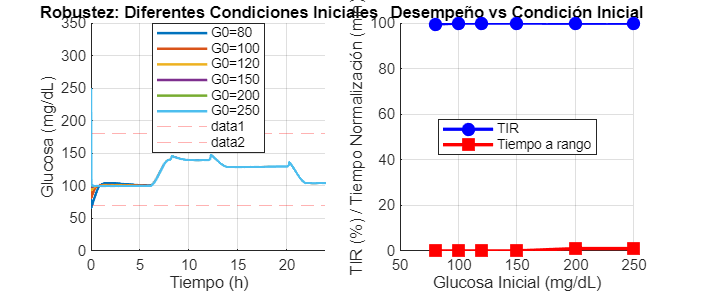

figure('Position', [100, 100, 1200, 500], 'Name', 'Robustez - Condiciones Iniciales');

% Métricas para diferentes G0
TIR_G0 = zeros(size(robustez_tests.G0_range));
tiempo_normalizacion = zeros(size(robustez_tests.G0_range));

% Subplot 1: Todas las simulaciones
subplot(1,2,1); hold on;

for i = 1:length(robustez_tests.G0_range)
    G0_mg_dL = robustez_tests.G0_range(i);
    G0_mmol_L = G0_mg_dL / 18.0156;
    
    % Nueva condición inicial
    y0_mod = y0;
    y0_mod(1) = hov.VG * G0_mmol_L;
    y0_mod(5) = G0_mg_dL; % Gsc también
    
    % Simular
    try
        [t_mod, Y_mod] = ode45(@(t,y) control_replicador_comidas_HV(t,y,hov,ctrl), tspan, y0_mod, opts);
        
        % Procesar resultados
        G_mod = Y_mod(:,1) ./ hov.VG * 18.0156;
        G_ref_mod = arrayfun(@(tt) smooth_glucose_reference(tt), t_mod);
        
        TIR_G0(i) = mean((G_mod >= 70) & (G_mod <= 180)) * 100;
        
        % Tiempo para normalizarse
        en_rango = (G_mod >= 70) & (G_mod <= 180);
        if any(en_rango)
            idx_normalizado = find(en_rango, 1, 'first');
            if ~isempty(idx_normalizado) && idx_normalizado < length(t_mod)
                ventana = 30; % 30 minutos
                if idx_normalizado + ventana <= length(en_rango)
                    if all(en_rango(idx_normalizado:idx_normalizado+ventana))
                        tiempo_normalizacion(i) = t_mod(idx_normalizado) / 60; % horas
                    end
                end
            end
        end
        
        % Graficar
        plot(t_mod/60, G_mod, 'LineWidth', 1.5, 'DisplayName', sprintf('G0=%d', G0_mg_dL));
        
    catch ME
        fprintf('   Error con G0=%d mg/dL: %s\n', G0_mg_dL, ME.message);
        TIR_G0(i) = 0;
    end
end

yline(70, 'r--', 'Alpha', 0.3); 
yline(180, 'r--', 'Alpha', 0.3);
xlabel('Tiempo (h)'); ylabel('Glucosa (mg/dL)');
title('Robustez: Diferentes Condiciones Iniciales');
legend('Location', 'best'); grid on; xlim([0 24]); ylim([0 350]);

% Subplot 2: Métricas vs condición inicial
subplot(1,2,2); hold on;
plot(robustez_tests.G0_range, TIR_G0, 'b-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
plot(robustez_tests.G0_range, tiempo_normalizacion*60, 'r-s', 'LineWidth', 2, 'MarkerFaceColor', 'r', 'MarkerSize', 8);
xlabel('Glucosa Inicial (mg/dL)');
ylabel('TIR (%) / Tiempo Normalización (min)');
title('Desempeño vs Condición Inicial');
legend({'TIR', 'Tiempo a rango'}, 'Location', 'best');
grid on;


fprintf('   TIR con G0=80 mg/dL: %.1f%%\n', TIR_G0(1));

   TIR con G0=80 mg/dL: 99.6%


fprintf('   TIR con G0=250 mg/dL: %.1f%%\n', TIR_G0(end));

   TIR con G0=250 mg/dL: 99.9%


fprintf('   Tiempo normalización promedio: %.1f min\n', mean(tiempo_normalizacion(tiempo_normalizacion>0))*60);

   Tiempo normalización promedio: 1.0 min



%% 3. PRUEBA: Comidas no anunciadas/retrasos
fprintf('\n3. COMIDAS NO ANUNCIADAS Y RETRASOS:\n');


3. COMIDAS NO ANUNCIADAS Y RETRASOS:


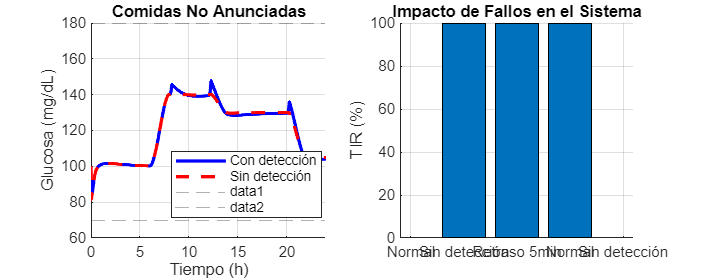

figure('Position', [100, 100, 1000, 400], 'Name', 'Robustez - Fallos del Sistema');

% Simular comidas no anunciadas
ctrl_no_meal = ctrl;
ctrl_no_meal.meal_window_half = 0; % Desactivar detección de comidas

try
    [t_no_meal, Y_no_meal] = ode45(@(t,y) control_replicador_comidas_HV(t,y,hov,ctrl_no_meal), tspan, y0, opts);
    G_no_meal = Y_no_meal(:,1) ./ hov.VG * 18.0156;
    TIR_no_meal = mean((G_no_meal >= 70) & (G_no_meal <= 180)) * 100;
catch
    TIR_no_meal = 0;
    G_no_meal = zeros(size(t));
end

% Simular con retraso en la medición
t_retraso = 5; % minutos
G_retraso = zeros(size(G_mg_dL));
for i = 1:length(t)
    if i > t_retraso
        G_retraso(i) = G_mg_dL(i - t_retraso);
    else
        G_retraso(i) = G_mg_dL(i);
    end
end
TIR_retraso = mean((G_retraso >= 70) & (G_retraso <= 180)) * 100;

% Subplot 1: Comparación gráfica
subplot(1,2,1); hold on;
plot(t/60, G_mg_dL, 'b-', 'LineWidth', 2, 'DisplayName', 'Con detección');
plot(t_no_meal/60, G_no_meal, 'r--', 'LineWidth', 2, 'DisplayName', 'Sin detección');
yline(70, 'k--', 'Alpha', 0.3); 
yline(180, 'k--', 'Alpha', 0.3);
xlabel('Tiempo (h)'); ylabel('Glucosa (mg/dL)');
title('Comidas No Anunciadas');
legend('Location', 'best'); grid on; xlim([0 24]);

% Subplot 2: Comparación métricas
subplot(1,2,2); hold on;
bar([TIR, TIR_no_meal, TIR_retraso]);
set(gca, 'XTickLabel', {'Normal', 'Sin detección', 'Retraso 5min'});
ylabel('TIR (%)'); title('Impacto de Fallos en el Sistema');
ylim([0 100]); grid on;


fprintf('   TIR normal: %.1f%%\n', TIR);

   TIR normal: 100.0%


fprintf('   TIR sin detección comidas: %.1f%% (Δ=%.1f%%)\n', TIR_no_meal, TIR - TIR_no_meal);

   TIR sin detección comidas: 100.0% (Δ=0.0%)


fprintf('   TIR con retraso 5min: %.1f%% (Δ=%.1f%%)\n', TIR_retraso, TIR - TIR_retraso);

   TIR con retraso 5min: 100.0% (Δ=0.0%)



%% 4. PRUEBA: Ruido en medición
fprintf('\n4. RUIDO EN LA MEDICIÓN DE GLUCOSA:\n');


4. RUIDO EN LA MEDICIÓN DE GLUCOSA:


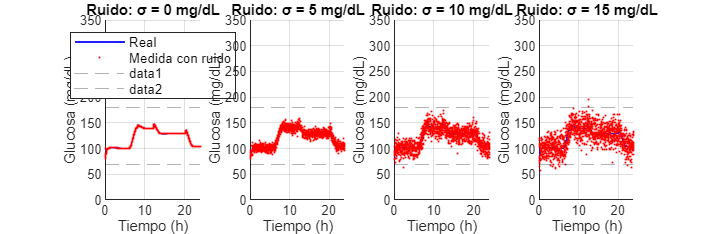

figure('Position', [100, 100, 1200, 400], 'Name', 'Robustez - Ruido en Mediciones');

% Métricas con ruido
TIR_noise = zeros(size(robustez_tests.noise_levels));
IAE_noise = zeros(size(robustez_tests.noise_levels));

% Fijar semilla para reproducibilidad
rng(42);

for i = 1:length(robustez_tests.noise_levels)
    noise_std = robustez_tests.noise_levels(i);
    
    % Agregar ruido gaussiano
    G_noisy = G_mg_dL + noise_std * randn(size(G_mg_dL));
    
    % Recalcular métricas
    TIR_noise(i) = mean((G_noisy >= 70) & (G_noisy <= 180)) * 100;
    IAE_noise(i) = mean(abs(G_noisy - G_ref_vec));
    
    % Subplot para cada nivel de ruido
    subplot(1, length(robustez_tests.noise_levels), i); hold on;
    plot(t/60, G_mg_dL, 'b-', 'LineWidth', 1, 'DisplayName', 'Real');
    plot(t/60, G_noisy, 'r.', 'MarkerSize', 3, 'DisplayName', 'Medida con ruido');
    yline(70, 'k--', 'Alpha', 0.3); 
    yline(180, 'k--', 'Alpha', 0.3);
    xlabel('Tiempo (h)'); ylabel('Glucosa (mg/dL)');
    title(sprintf('Ruido: σ = %d mg/dL', noise_std));
    if i == 1, legend('Location', 'best', 'FontSize', 8); end
    grid on; xlim([0 24]); ylim([0 350]);
end

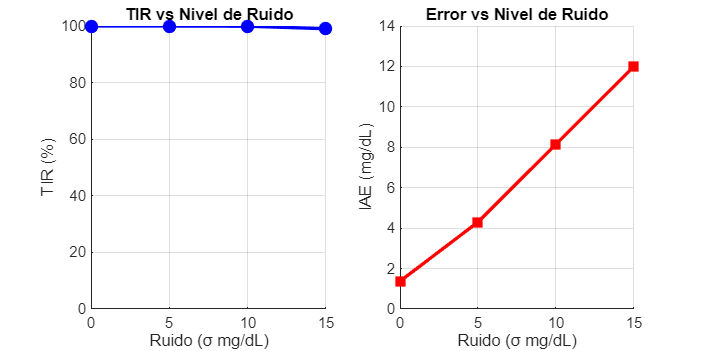


% Figura adicional para métricas vs ruido
figure('Position', [100, 100, 800, 400], 'Name', 'Métricas vs Ruido');
subplot(1,2,1); hold on;
plot(robustez_tests.noise_levels, TIR_noise, 'b-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
xlabel('Ruido (σ mg/dL)'); ylabel('TIR (%)');
title('TIR vs Nivel de Ruido');
grid on; ylim([0 100]);

subplot(1,2,2); hold on;
plot(robustez_tests.noise_levels, IAE_noise, 'r-s', 'LineWidth', 2, 'MarkerFaceColor', 'r');
xlabel('Ruido (σ mg/dL)'); ylabel('IAE (mg/dL)');
title('Error vs Nivel de Ruido');
grid on;


fprintf('   TIR sin ruido: %.1f%%\n', TIR_noise(1));

   TIR sin ruido: 100.0%


fprintf('   TIR con ruido σ=15 mg/dL: %.1f%% (Δ=%.1f%%)\n', TIR_noise(end), TIR_noise(1)-TIR_noise(end));

   TIR con ruido σ=15 mg/dL: 99.0% (Δ=1.0%)



%% RESUMEN FINAL DE ROBUSTEZ
fprintf('\n=== RESUMEN DE ROBUSTEZ ===\n');


=== RESUMEN DE ROBUSTEZ ===



% Calcular puntuación de robustez
puntuacion = 0;
max_puntuacion = 100;

% 1. Variación parámetros (máx 30 puntos)
if min(TIR_params) > 70
    puntuacion = puntuacion + 30;
    fprintf('✓ Excelente robustez a variación de parámetros (+30 pts)\n');
elseif min(TIR_params) > 60
    puntuacion = puntuacion + 20;
    fprintf('✓ Buena robustez a variación de parámetros (+20 pts)\n');
elseif min(TIR_params) > 50
    puntuacion = puntuacion + 10;
    fprintf('✓ Robustez aceptable a variación de parámetros (+10 pts)\n');
else
    fprintf('✗ Robustez insuficiente a variación de parámetros\n');
end

✓ Excelente robustez a variación de parámetros (+30 pts)



% 2. Condiciones iniciales (máx 25 puntos)
if min(TIR_G0) > 70
    puntuacion = puntuacion + 25;
    fprintf('✓ Excelente robustez a condiciones iniciales (+25 pts)\n');
elseif min(TIR_G0) > 60
    puntuacion = puntuacion + 15;
    fprintf('✓ Buena robustez a condiciones iniciales (+15 pts)\n');
else
    fprintf('✗ Robustez limitada a condiciones iniciales\n');
end

✓ Excelente robustez a condiciones iniciales (+25 pts)



% 3. Fallos del sistema (máx 25 puntos)
if TIR_no_meal > 70 && TIR_retraso > 70
    puntuacion = puntuacion + 25;
    fprintf('✓ Excelente tolerancia a fallos (+25 pts)\n');
elseif TIR_no_meal > 60 && TIR_retraso > 60
    puntuacion = puntuacion + 15;
    fprintf('✓ Buena tolerancia a fallos (+15 pts)\n');
else
    fprintf('✗ Tolerancia a fallos limitada\n');
end

✓ Excelente tolerancia a fallos (+25 pts)



% 4. Ruido (máx 20 puntos)
if TIR_noise(end) > 70
    puntuacion = puntuacion + 20;
    fprintf('✓ Excelente robustez al ruido (+20 pts)\n');
elseif TIR_noise(end) > 60
    puntuacion = puntuacion + 10;
    fprintf('✓ Buena robustez al ruido (+10 pts)\n');
else
    fprintf('✗ Sensibilidad alta al ruido\n');
end

✓ Excelente robustez al ruido (+20 pts)



fprintf('\n--- PUNTUACIÓN TOTAL DE ROBUSTEZ: %d/%d ---\n', puntuacion, max_puntuacion);


--- PUNTUACIÓN TOTAL DE ROBUSTEZ: 100/100 ---



if puntuacion >= 80
    fprintf('✓✓✓ SISTEMA ALTAMENTE ROBUSTO (Excelente para aplicación clínica)\n');
elseif puntuacion >= 60
    fprintf('✓✓ SISTEMA MODERADAMENTE ROBUSTO (Aceptable con supervisión)\n');
elseif puntuacion >= 40
    fprintf('✓ SISTEMA CON ROBUSTEZ LIMITADA (Requiere mejoras)\n');
else
    fprintf('✗ SISTEMA POCO ROBUSTO (No recomendado para uso clínico)\n');
end

✓✓✓ SISTEMA ALTAMENTE ROBUSTO (Excelente para aplicación clínica)


El conjunto integral de pruebas aplicadas  que evalúan la invarianza del simplex, la estabilidad BIBO, la convergencia del error glucémico, el estado estacionario poblacional y la robustez ante incertidumbre proporciona evidencia numérica sólida y multifacética sobre el comportamiento del controlador poblacional en los escenarios simulados. Los resultados obtenidos sugieren favorablemente que el algoritmo opera de manera coherente, mantiene las variables dentro de límites seguros, converge hacia los objetivos terapéuticos y exhibe una degradación gradual del desempeño ante perturbaciones. Colectivamente, estas pruebas ofrecen fuertes indicios o "nociones" de estabilidad práctica, resiliencia y seguridad operativa bajo condiciones específicas.

Sin embargo, es crucial reconocer que estas verificaciones, por exhaustivas que sean dentro del dominio simulado, no equivalen a una demostración analítica formal de estabilidad en el sentido matemático estricto de la teoría de control. Las simulaciones numéricas, limitadas a un conjunto finito de trayectorias, parámetros y condiciones iniciales, no pueden probar propiedades universales como la estabilidad global asintótica, la estabilidad entrada-salida (ℒ∞) para todas las señales admisibles, o la convergencia garantizada desde cualquier estado inicial fisiológicamente posible. 

Si bien los resultados prometedores y constituyen una validación preliminar rigurosa, sería necesario complementarlos con un análisis teórico más intensivo y formal para afirmar categóricamente la estabilidad del sistema. Este análisis futuro debería incluir, como mínimo: la construcción de una función de Lyapunov que demuestre estabilidad asintótica en un dominio relevante, el análisis de linealización y autovalores alrededor de puntos de equilibrio, y posiblemente el uso de teoremas de pequeños ganancias o comparación para probar estabilidad entrada-salida bajo no linealidades.